# Irminger 6 CTD Casts

First produces a rough map of the CTD casts from Irminger 6 in the vicinity of OOI assets. Each CTD cast is then plotted for temperature, salinity, and dissolved oxygen. 

Kristen Fogaren 12/3/2020

- Data was downloaded from Alfresco

- Data conversion with Seabird Software

- Processed casts in Python and output to CSV

- Read into Matab as tables

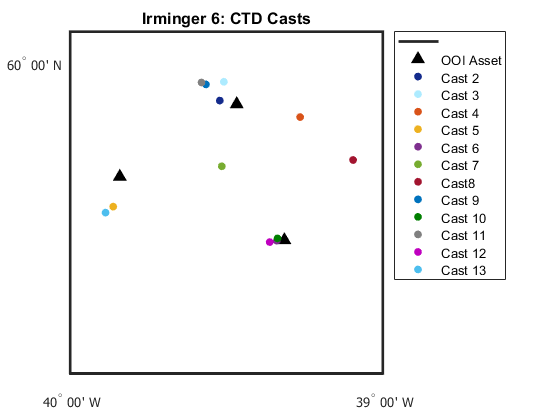

% Set up workspace 
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\My Drive\Matlab_work\BC\IrmingerData\Year6')
load Irm6_CTD_Casts.mat

% OOI asset locations 
ooi_latlon = [59.9341, -39.4673
    59.8177, -39.8412
    59.7155, -39.3148];
    
% Setup the Map Axes
figure
axesm('MapProjection','mercator'); 
minlat=min(ooi_latlon(:,1)); maxlat=max(ooi_latlon(:,1)); 
minlon=min(ooi_latlon(:,2)); maxlon=max(ooi_latlon(:,1)); 

% New Lat/Lon Limits
ll = [-40 59.5; -39 60.05];

setm(gca, 'MapLatLimit',[ll(1,2) ll(2,2)],...
          'MapLonLimit',[ll(1,1) ll(2,1)]);
setm(gca,'MLineLocation',1,'MLabelLocation',1,...
    'MeridianLabel','on','MLabelParallel','south'); 
setm(gca,'PLineLocation',1,'PLabelLocation',1,...
    'ParallelLabel','on','PLabelMeridian','west');
tightmap;
setm(gca,'FontWeight','normal','FontSize',10,'FontName','Tahoma','LabelUnits','dm'); 

% Add lat/lon tickmarks for every degree if the map spans 
% greater than 1.5 degrees longitude, or every quarter degree if less.
if abs(maxlon-minlon)>1.5
  setm(gca,'MLineLocation',1,'MLabelLocation',1,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',1,'PLabelLocation',1,'ParallelLabel','on','PLabelMeridian','west');
else
  setm(gca,'MLineLocation',0.25,'MLabelLocation',0.25,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',0.25,'PLabelLocation',0.25,'ParallelLabel','on','PLabelMeridian','west');
end

% Plot Casts/OOI Assets
plotm(ooi_latlon(:,1),ooi_latlon(:,2),'^','markersize',8,'MarkerFaceColor','k',...
    'MarkerEdgeColor','k')
hold on
plotm(nanmean(ar3505002down.latitude),nanmean(ar3505002down.longitude),'.','markersize',20,'Color',navy)
plotm(nanmean(ar3505003down.latitude),nanmean(ar3505003down.longitude),'.','markersize',20,'Color',lightcyan)
plotm(nanmean(ar3505004down.latitude),nanmean(ar3505004down.longitude),'.','markersize',20,'Color',red)
plotm(nanmean(ar3505005down.latitude),nanmean(ar3505005down.longitude),'.','markersize',20,'Color',yellow)
plotm(nanmean(ar3505006down.latitude),nanmean(ar3505006down.longitude),'.','markersize',20,'Color',purple)
plotm(nanmean(ar3505007down.latitude),nanmean(ar3505007down.longitude),'.','markersize',20,'Color',green)
plotm(nanmean(ar3505008down.latitude),nanmean(ar3505008down.longitude),'.','markersize',20,'Color',maroon)
plotm(nanmean(ar3505009down.latitude),nanmean(ar3505009down.longitude),'.','markersize',20,'Color',blue)
plotm(nanmean(ar3505010down.latitude),nanmean(ar3505010down.longitude),'.','markersize',20,'Color',forestgreen)
plotm(nanmean(ar3505011down.latitude),nanmean(ar3505011down.longitude),'.','markersize',20,'Color',grey)
plotm(nanmean(ar3505012down.latitude),nanmean(ar3505012down.longitude),'.','markersize',20,'Color',brightpurple)
plotm(nanmean(ar3505013down.latitude),nanmean(ar3505013down.longitude),'.','markersize',20,'Color',cyan)

title('Irminger 6: CTD Casts')
legend('','OOI Asset','Cast 2','Cast 3','Cast 4','Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 10','Cast 11','Cast 12','Cast 13','Location','bestoutside')

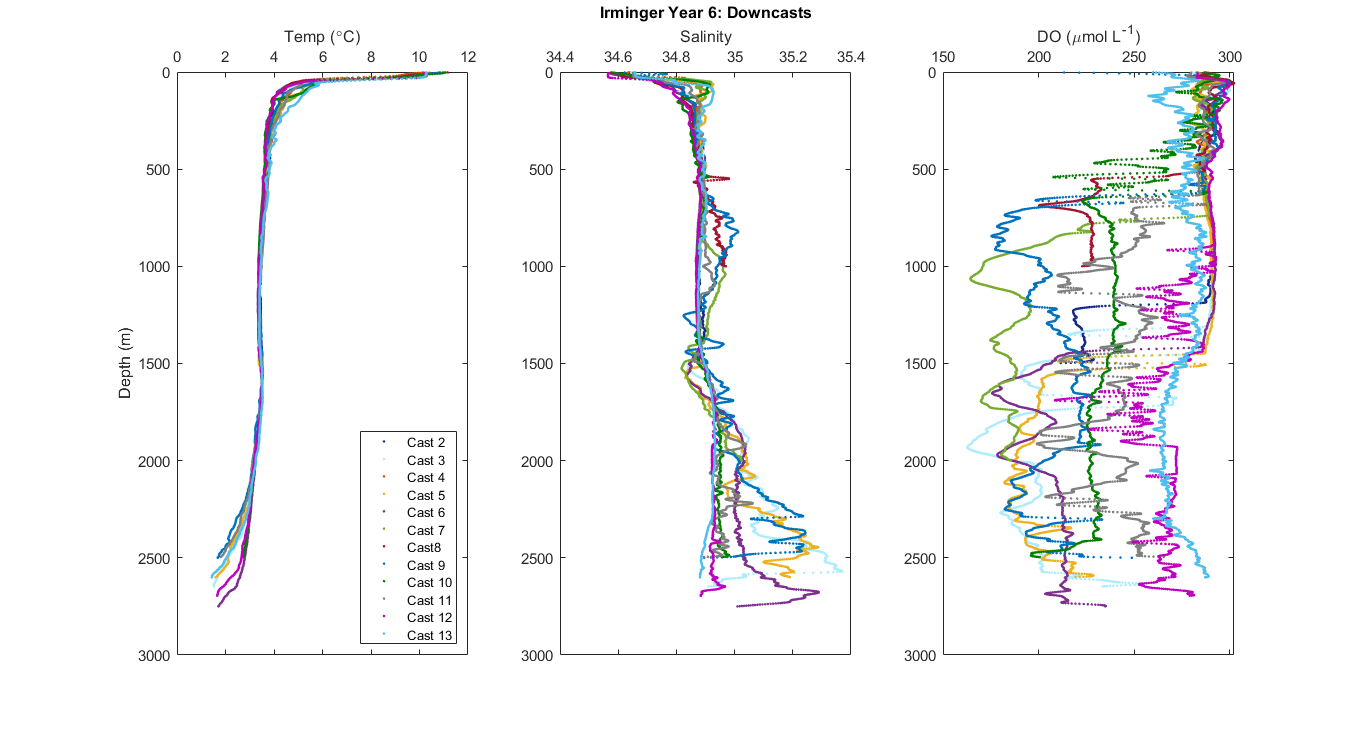

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505002down.t090C,ar3505002down.depSM,'.','Color',navy)
hold on
plot(ar3505003down.t090C,ar3505003down.depSM,'.','Color',lightcyan)
plot(ar3505004down.t090C,ar3505004down.depSM,'.','Color',red)
plot(ar3505005down.t090C,ar3505005down.depSM,'.','Color',yellow)
plot(ar3505006down.t090C,ar3505006down.depSM,'.','Color',purple)
plot(ar3505007down.t090C,ar3505007down.depSM,'.','Color',green)
plot(ar3505008down.t090C,ar3505008down.depSM,'.','Color',maroon)
plot(ar3505009down.t090C,ar3505009down.depSM,'.','Color',blue)
plot(ar3505010down.t090C,ar3505010down.depSM,'.','Color',forestgreen)
plot(ar3505011down.t090C,ar3505011down.depSM,'.','Color',grey)
plot(ar3505012down.t090C,ar3505012down.depSM,'.','Color',brightpurple)
plot(ar3505013down.t090C,ar3505013down.depSM,'.','Color',cyan)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 2','Cast 3','Cast 4','Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 10','Cast 11','Cast 12','Cast 13','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505002down.sal00,ar3505002down.depSM,'.','Color',navy)
hold on
plot(ar3505003down.sal00,ar3505003down.depSM,'.','Color',lightcyan)
plot(ar3505004down.sal00,ar3505004down.depSM,'.','Color',red)
plot(ar3505005down.sal00,ar3505005down.depSM,'.','Color',yellow)
plot(ar3505006down.sal00,ar3505006down.depSM,'.','Color',purple)
plot(ar3505007down.sal00,ar3505007down.depSM,'.','Color',green)
plot(ar3505008down.sal00,ar3505008down.depSM,'.','Color',maroon)
plot(ar3505009down.sal00,ar3505009down.depSM,'.','Color',blue)
plot(ar3505010down.sal00,ar3505010down.depSM,'.','Color',forestgreen)
plot(ar3505011down.sal00,ar3505011down.depSM,'.','Color',grey)
plot(ar3505012down.sal00,ar3505012down.depSM,'.','Color',brightpurple)
plot(ar3505013down.sal00,ar3505013down.depSM,'.','Color',cyan)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Downcasts')

s3 = subplot(1,3,3);
plot(ar3505002down.sbeox0MLL*44.661,ar3505002down.depSM,'.','Color',navy)
hold on
plot(ar3505003down.sbeox0MLL*44.661,ar3505003down.depSM,'.','Color',lightcyan)
plot(ar3505004down.sbeox0MLL*44.661,ar3505004down.depSM,'.','Color',red)
plot(ar3505005down.sbeox0MLL*44.661,ar3505005down.depSM,'.','Color',yellow)
plot(ar3505006down.sbeox0MLL*44.661,ar3505006down.depSM,'.','Color',purple)
plot(ar3505007down.sbeox0MLL*44.661,ar3505007down.depSM,'.','Color',green)
plot(ar3505008down.sbeox0MLL*44.661,ar3505008down.depSM,'.','Color',maroon)
plot(ar3505009down.sbeox0MLL*44.661,ar3505009down.depSM,'.','Color',blue)
plot(ar3505010down.sbeox0MLL*44.661,ar3505010down.depSM,'.','Color',forestgreen)
plot(ar3505011down.sbeox0MLL*44.661,ar3505011down.depSM,'.','Color',grey)
plot(ar3505012down.sbeox0MLL*44.661,ar3505012down.depSM,'.','Color',brightpurple)
plot(ar3505013down.sbeox0MLL*44.661,ar3505013down.depSM,'.','Color',cyan)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

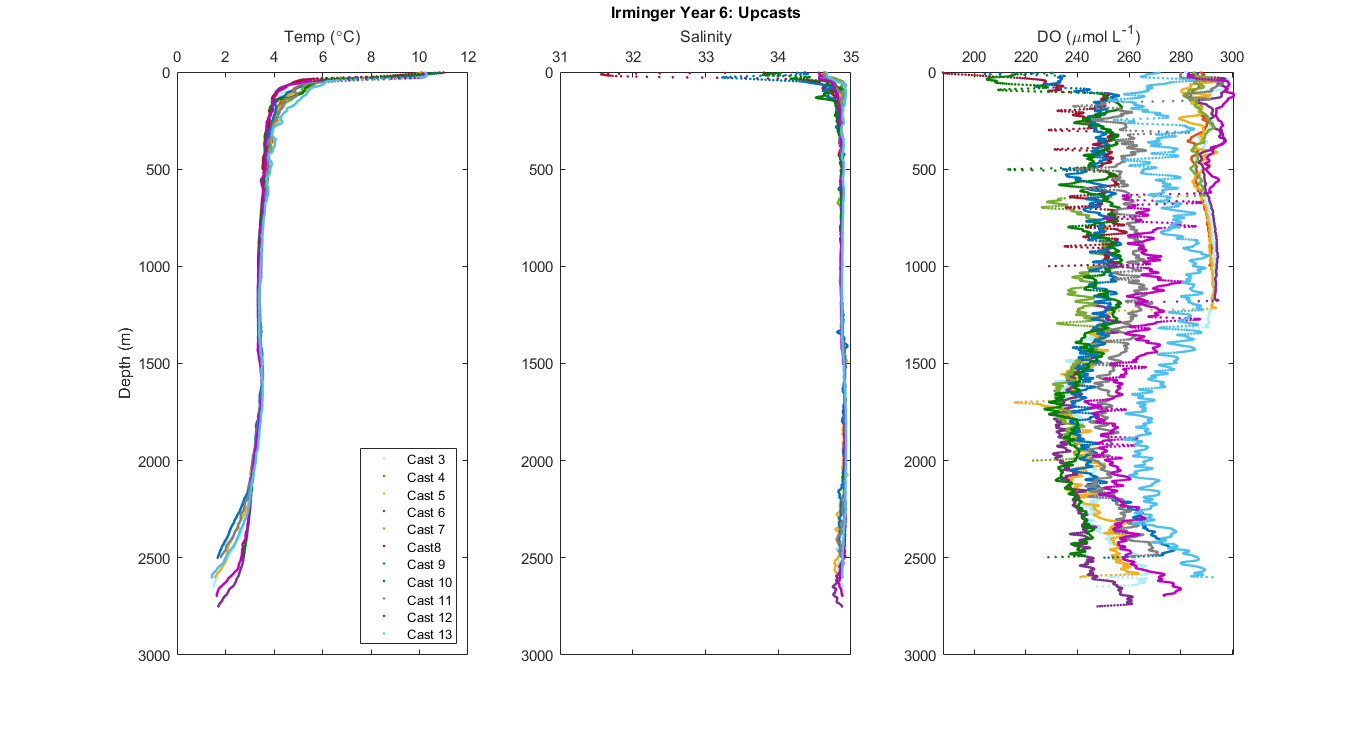

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
%plot(ar3505002up.t090C,ar3505002up.depSM,'.','Color',navy)
plot(ar3505003up.t090C,ar3505003up.depSM,'.','Color',lightcyan)
hold on
plot(ar3505004up.t090C,ar3505004up.depSM,'.','Color',red)
plot(ar3505005up.t090C,ar3505005up.depSM,'.','Color',yellow)
plot(ar3505006up.t090C,ar3505006up.depSM,'.','Color',purple)
plot(ar3505007up.t090C,ar3505007up.depSM,'.','Color',green)
plot(ar3505008up.t090C,ar3505008up.depSM,'.','Color',maroon)
plot(ar3505009up.t090C,ar3505009up.depSM,'.','Color',blue)
plot(ar3505010up.t090C,ar3505010up.depSM,'.','Color',forestgreen)
plot(ar3505011up.t090C,ar3505011up.depSM,'.','Color',grey)
plot(ar3505012up.t090C,ar3505012up.depSM,'.','Color',brightpurple)
plot(ar3505013up.t090C,ar3505013up.depSM,'.','Color',cyan)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 3','Cast 4','Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 10','Cast 11','Cast 12','Cast 13','Location','SE')

s2 = subplot(1,3,2);
%plot(ar3505002up.sal00,ar3505002up.depSM,'.','Color',navy)
plot(ar3505003up.sal00,ar3505003up.depSM,'.','Color',lightcyan)
hold on
plot(ar3505004up.sal00,ar3505004up.depSM,'.','Color',red)
plot(ar3505005up.sal00,ar3505005up.depSM,'.','Color',yellow)
plot(ar3505006up.sal00,ar3505006up.depSM,'.','Color',purple)
plot(ar3505007up.sal00,ar3505007up.depSM,'.','Color',green)
plot(ar3505008up.sal00,ar3505008up.depSM,'.','Color',maroon)
plot(ar3505009up.sal00,ar3505009up.depSM,'.','Color',blue)
plot(ar3505010up.sal00,ar3505010up.depSM,'.','Color',forestgreen)
plot(ar3505011up.sal00,ar3505011up.depSM,'.','Color',grey)
plot(ar3505012up.sal00,ar3505012up.depSM,'.','Color',brightpurple)
plot(ar3505013up.sal00,ar3505013up.depSM,'.','Color',cyan)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Upcasts')

s3 = subplot(1,3,3);
%plot(ar3505002up.sbeox0MLL*44.661,ar3505002up.depSM,'.','Color',navy)
plot(ar3505003up.sbeox0MLL*44.661,ar3505003up.depSM,'.','Color',lightcyan)
hold on
plot(ar3505004up.sbeox0MLL*44.661,ar3505004up.depSM,'.','Color',red)
plot(ar3505005up.sbeox0MLL*44.661,ar3505005up.depSM,'.','Color',yellow)
plot(ar3505006up.sbeox0MLL*44.661,ar3505006up.depSM,'.','Color',purple)
plot(ar3505007up.sbeox0MLL*44.661,ar3505007up.depSM,'.','Color',green)
plot(ar3505008up.sbeox0MLL*44.661,ar3505008up.depSM,'.','Color',maroon)
plot(ar3505009up.sbeox0MLL*44.661,ar3505009up.depSM,'.','Color',blue)
plot(ar3505010up.sbeox0MLL*44.661,ar3505010up.depSM,'.','Color',forestgreen)
plot(ar3505011up.sbeox0MLL*44.661,ar3505011up.depSM,'.','Color',grey)
plot(ar3505012up.sbeox0MLL*44.661,ar3505012up.depSM,'.','Color',brightpurple)
plot(ar3505013up.sbeox0MLL*44.661,ar3505013up.depSM,'.','Color',cyan)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

- Colors in CTD plots correspond to location colors in the map above. 

## Upcasts versus Downcasts 

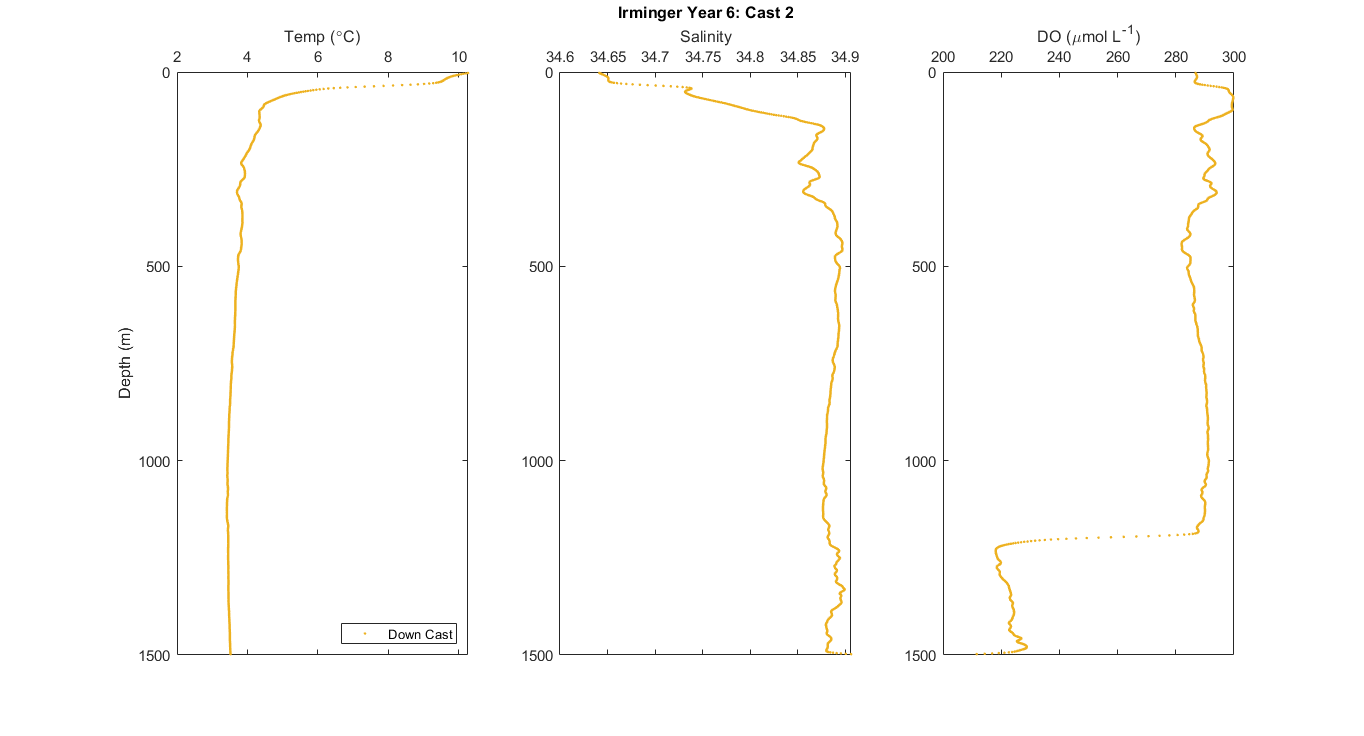

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505002down.t090C,ar3505002down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505002down.sal00,ar3505002down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 2')

s3 = subplot(1,3,3);
plot(ar3505002down.sbeox0MLL*44.661,ar3505002down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

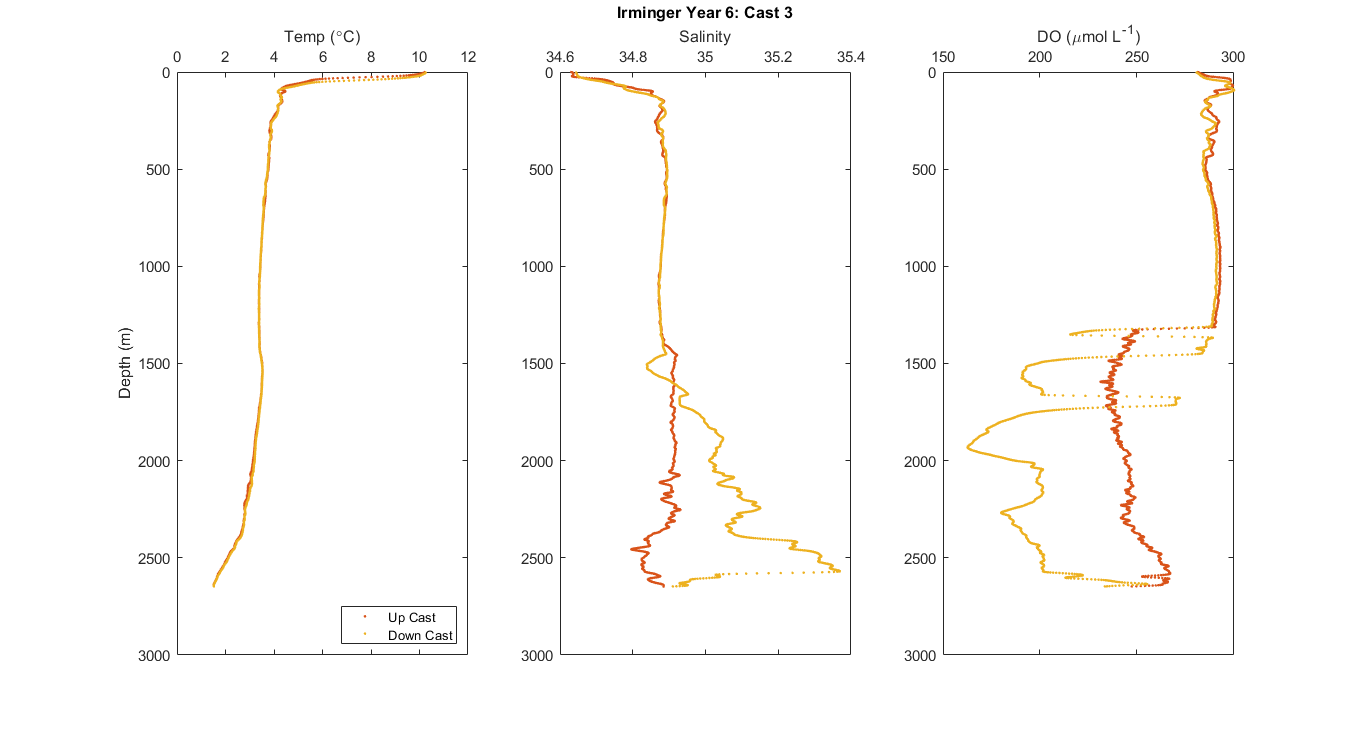



f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505003up.t090C,ar3505003up.depSM,'.','Color',red);
hold on
plot(ar3505003down.t090C,ar3505003down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505003up.sal00,ar3505003up.depSM,'.','Color',red);
hold on
plot(ar3505003down.sal00,ar3505003down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 3')

s3 = subplot(1,3,3);
plot(ar3505003up.sbeox0MLL*44.661,ar3505003up.depSM,'.','Color',red);
hold on
plot(ar3505003down.sbeox0MLL*44.661,ar3505003down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

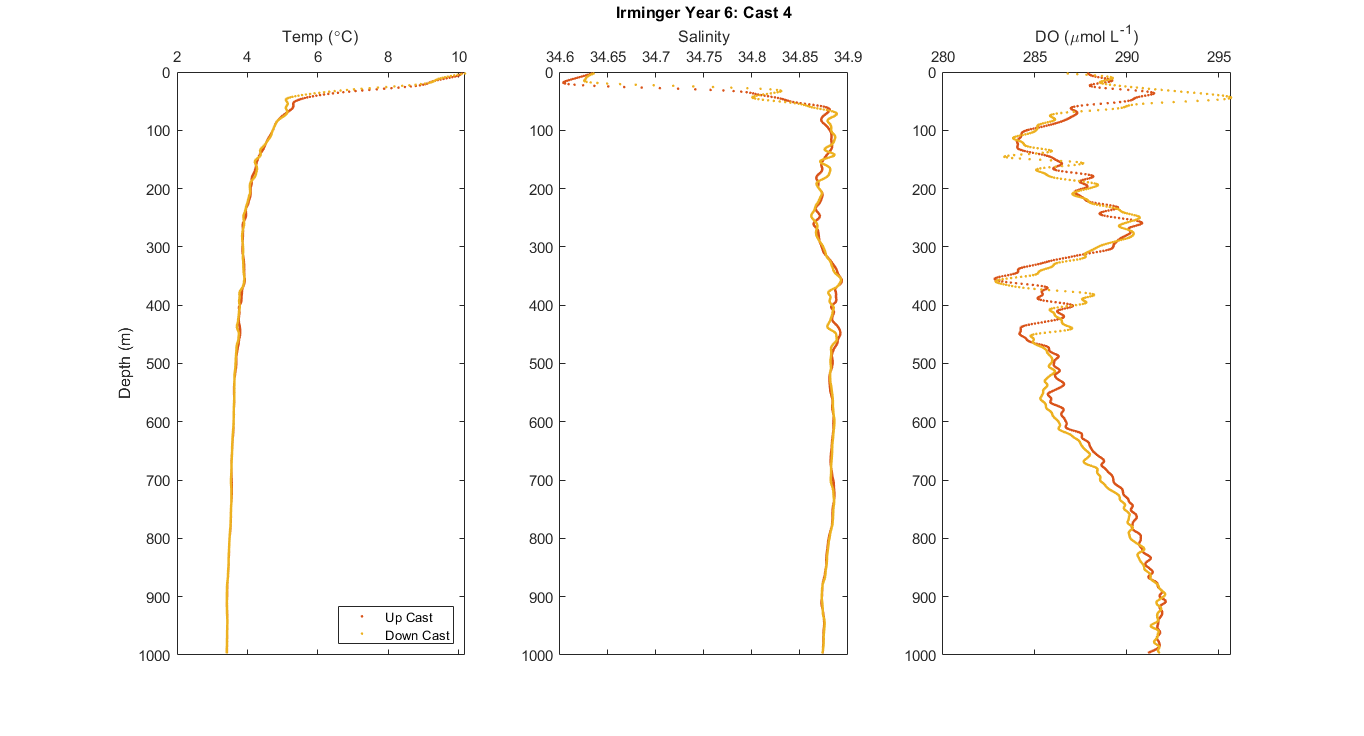



f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505004up.t090C,ar3505004up.depSM,'.','Color',red);
hold on
plot(ar3505004down.t090C,ar3505004down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505004up.sal00,ar3505004up.depSM,'.','Color',red);
hold on
plot(ar3505004down.sal00,ar3505004down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 4')

s3 = subplot(1,3,3);
plot(ar3505004up.sbeox0MLL*44.661,ar3505004up.depSM,'.','Color',red);
hold on
plot(ar3505004down.sbeox0MLL*44.661,ar3505004down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

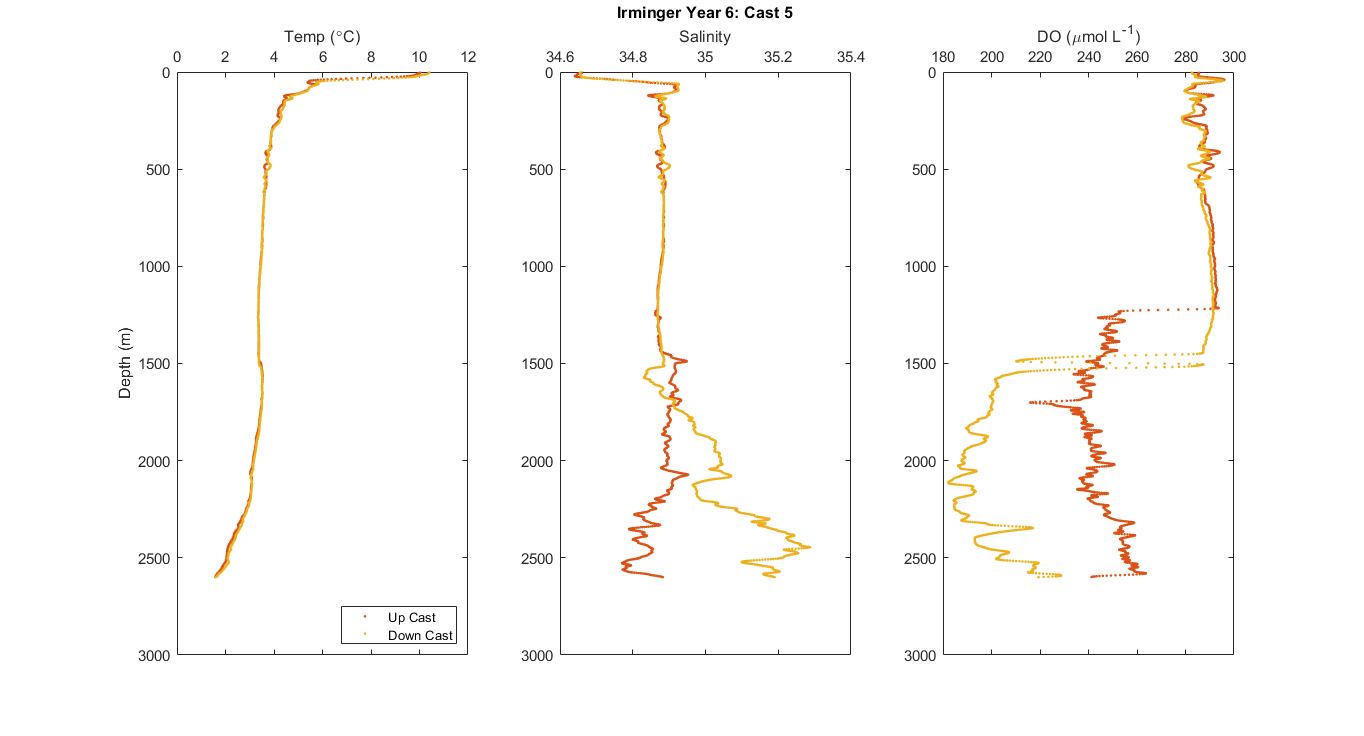

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505005up.t090C,ar3505005up.depSM,'.','Color',red);
hold on
plot(ar3505005down.t090C,ar3505005down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505005up.sal00,ar3505005up.depSM,'.','Color',red);
hold on
plot(ar3505005down.sal00,ar3505005down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 5')

s3 = subplot(1,3,3);
plot(ar3505005up.sbeox0MLL*44.661,ar3505005up.depSM,'.','Color',red);
hold on
plot(ar3505005down.sbeox0MLL*44.661,ar3505005down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

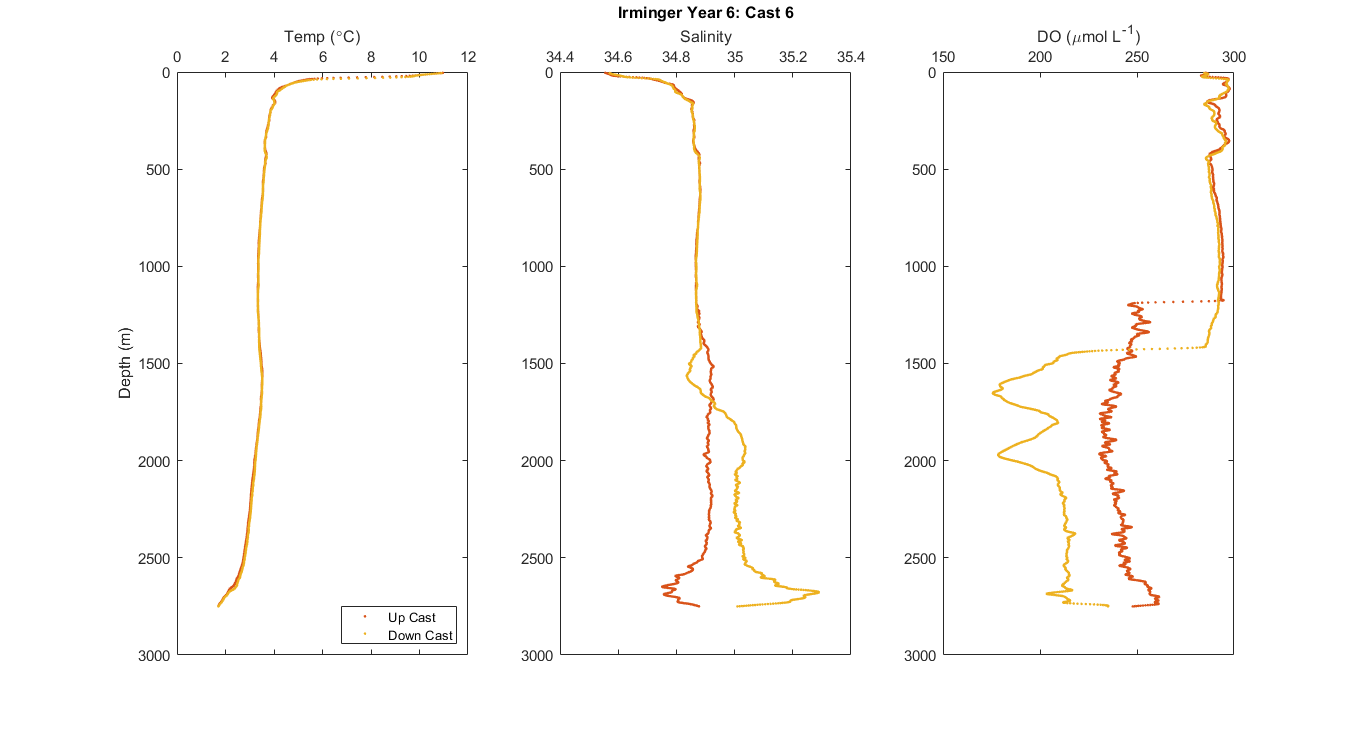

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505006up.t090C,ar3505006up.depSM,'.','Color',red);
hold on
plot(ar3505006down.t090C,ar3505006down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505006up.sal00,ar3505006up.depSM,'.','Color',red);
hold on
plot(ar3505006down.sal00,ar3505006down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 6')

s3 = subplot(1,3,3);
plot(ar3505006up.sbeox0MLL*44.661,ar3505006up.depSM,'.','Color',red);
hold on
plot(ar3505006down.sbeox0MLL*44.661,ar3505006down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

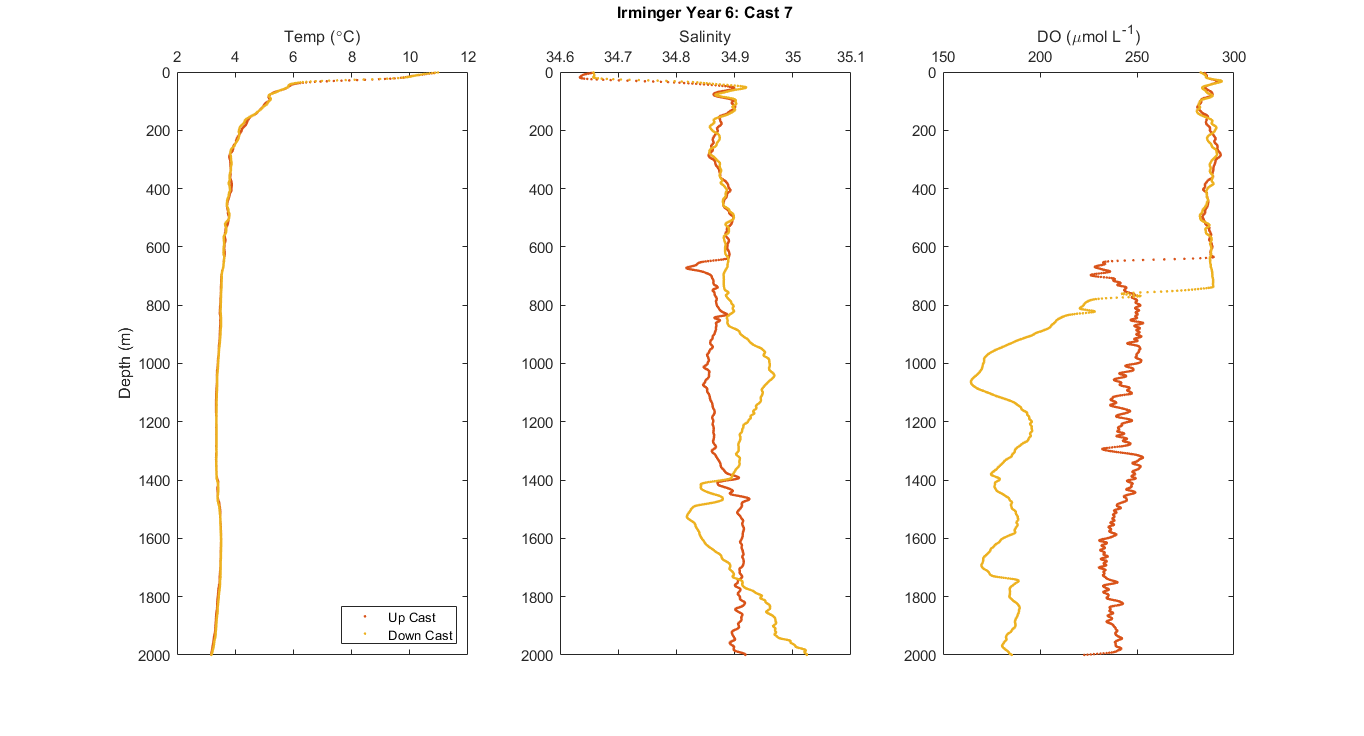

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505007up.t090C,ar3505007up.depSM,'.','Color',red);
hold on
plot(ar3505007down.t090C,ar3505007down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505007up.sal00,ar3505007up.depSM,'.','Color',red);
hold on
plot(ar3505007down.sal00,ar3505007down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 7')

s3 = subplot(1,3,3);
plot(ar3505007up.sbeox0MLL*44.661,ar3505007up.depSM,'.','Color',red);
hold on
plot(ar3505007down.sbeox0MLL*44.661,ar3505007down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

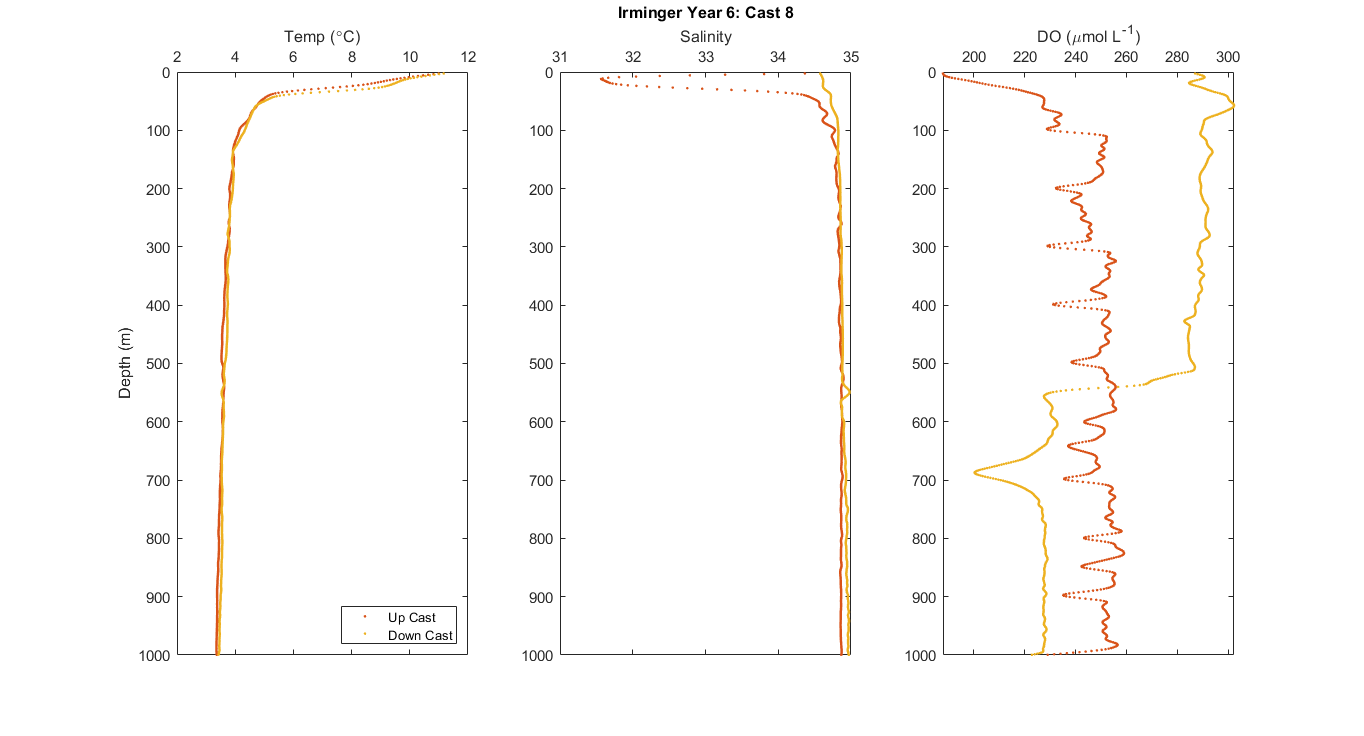

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505008up.t090C,ar3505008up.depSM,'.','Color',red);
hold on
plot(ar3505008down.t090C,ar3505008down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505008up.sal00,ar3505008up.depSM,'.','Color',red);
hold on
plot(ar3505008down.sal00,ar3505008down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 8')

s3 = subplot(1,3,3);
plot(ar3505008up.sbeox0MLL*44.661,ar3505008up.depSM,'.','Color',red);
hold on
plot(ar3505008down.sbeox0MLL*44.661,ar3505008down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

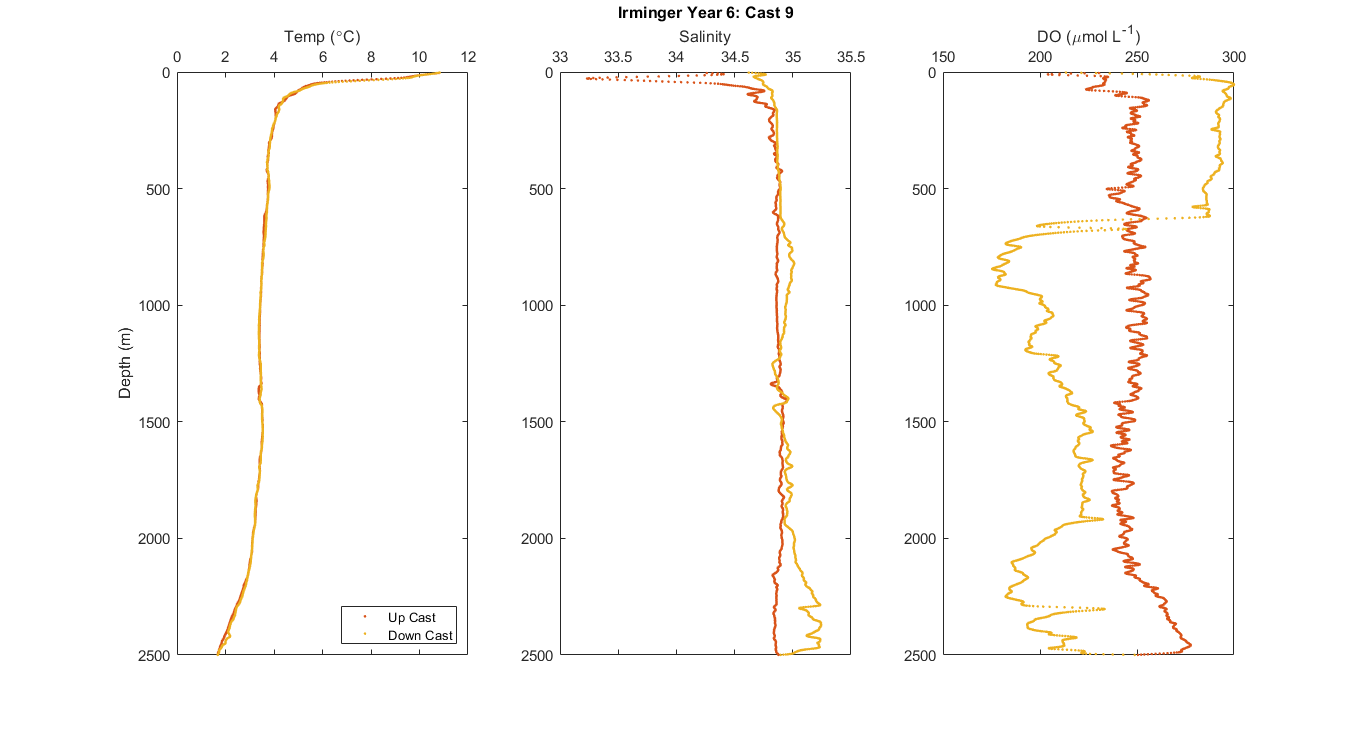


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505009up.t090C,ar3505009up.depSM,'.','Color',red);
hold on
plot(ar3505009down.t090C,ar3505009down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505009up.sal00,ar3505009up.depSM,'.','Color',red);
hold on
plot(ar3505009down.sal00,ar3505009down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 9')

s3 = subplot(1,3,3);
plot(ar3505009up.sbeox0MLL*44.661,ar3505009up.depSM,'.','Color',red);
hold on
plot(ar3505009down.sbeox0MLL*44.661,ar3505009down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

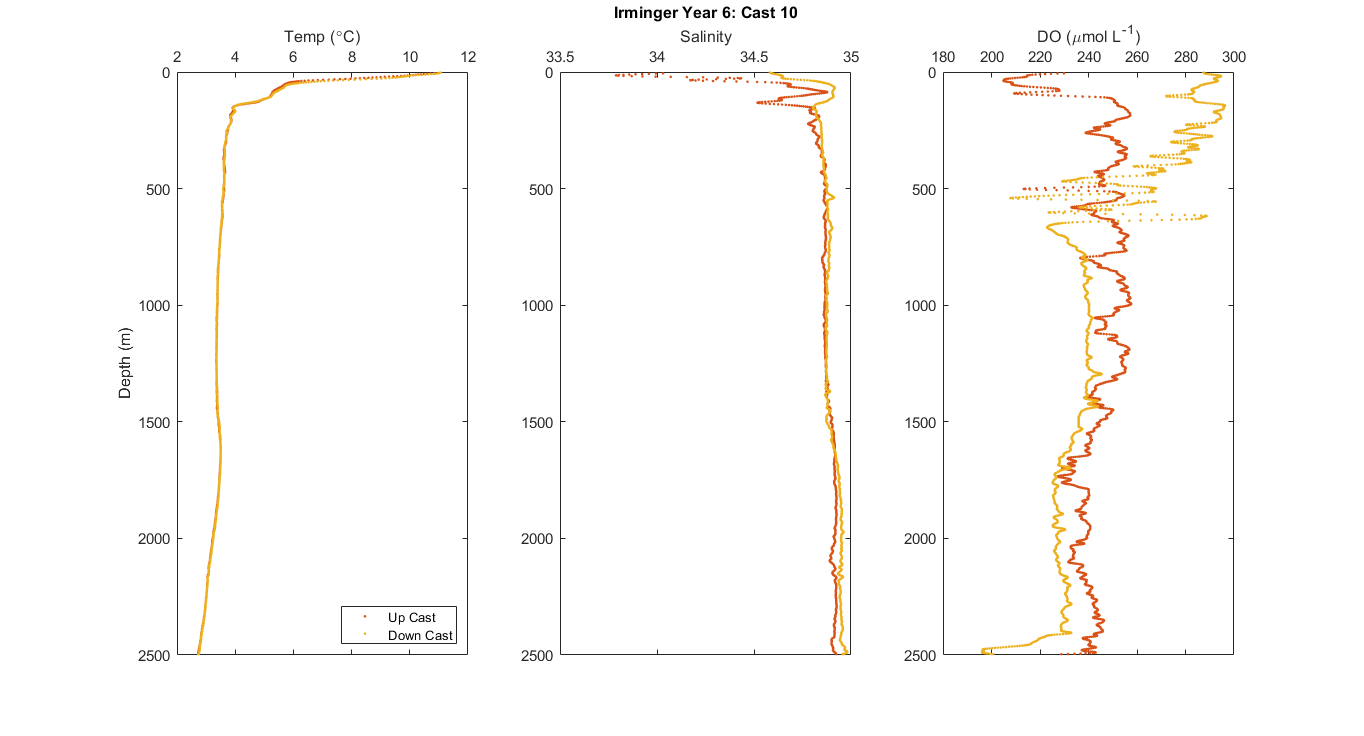


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505010up.t090C,ar3505010up.depSM,'.','Color',red);
hold on
plot(ar3505010down.t090C,ar3505010down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505010up.sal00,ar3505010up.depSM,'.','Color',red);
hold on
plot(ar3505010down.sal00,ar3505010down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 10')

s3 = subplot(1,3,3);
plot(ar3505010up.sbeox0MLL*44.661,ar3505010up.depSM,'.','Color',red);
hold on
plot(ar3505010down.sbeox0MLL*44.661,ar3505010down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

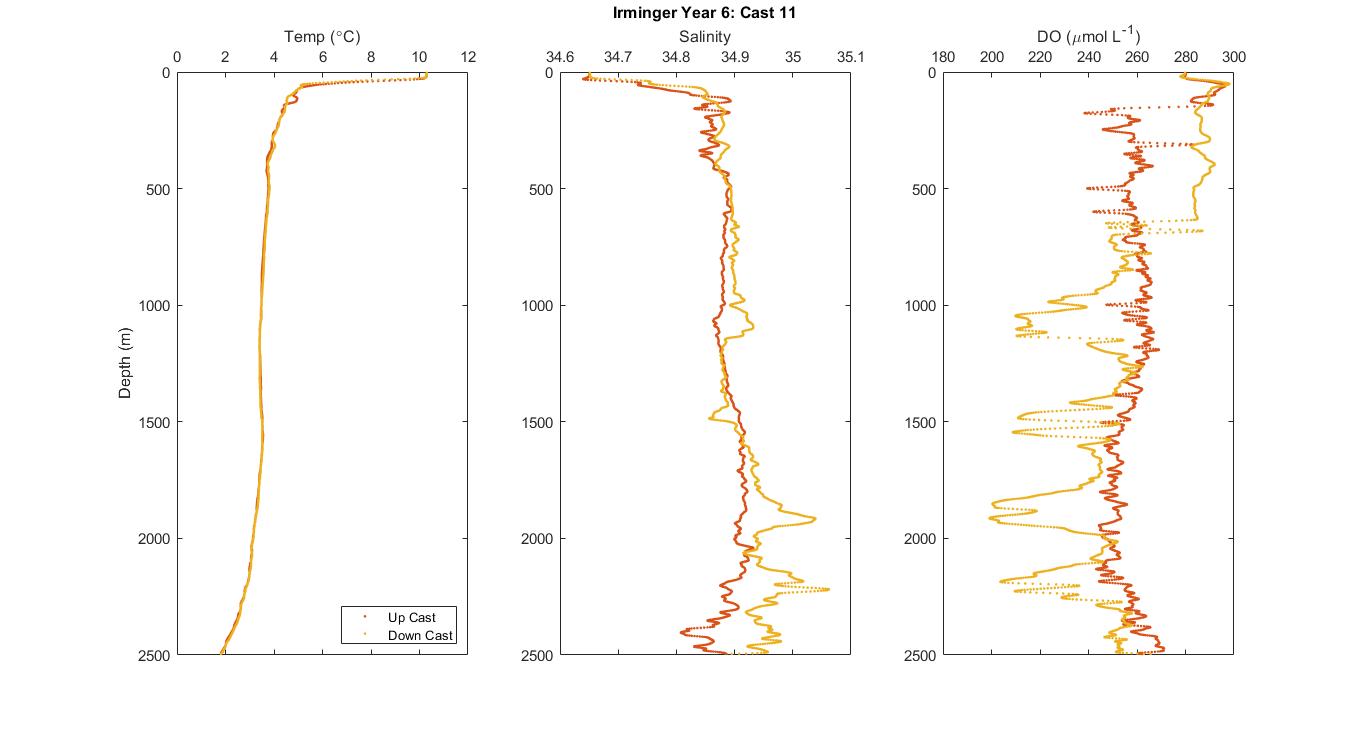


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505011up.t090C,ar3505011up.depSM,'.','Color',red);
hold on
plot(ar3505011down.t090C,ar3505011down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505011up.sal00,ar3505011up.depSM,'.','Color',red);
hold on
plot(ar3505011down.sal00,ar3505011down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 11')

s3 = subplot(1,3,3);
plot(ar3505011up.sbeox0MLL*44.661,ar3505011up.depSM,'.','Color',red);
hold on
plot(ar3505011down.sbeox0MLL*44.661,ar3505011down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

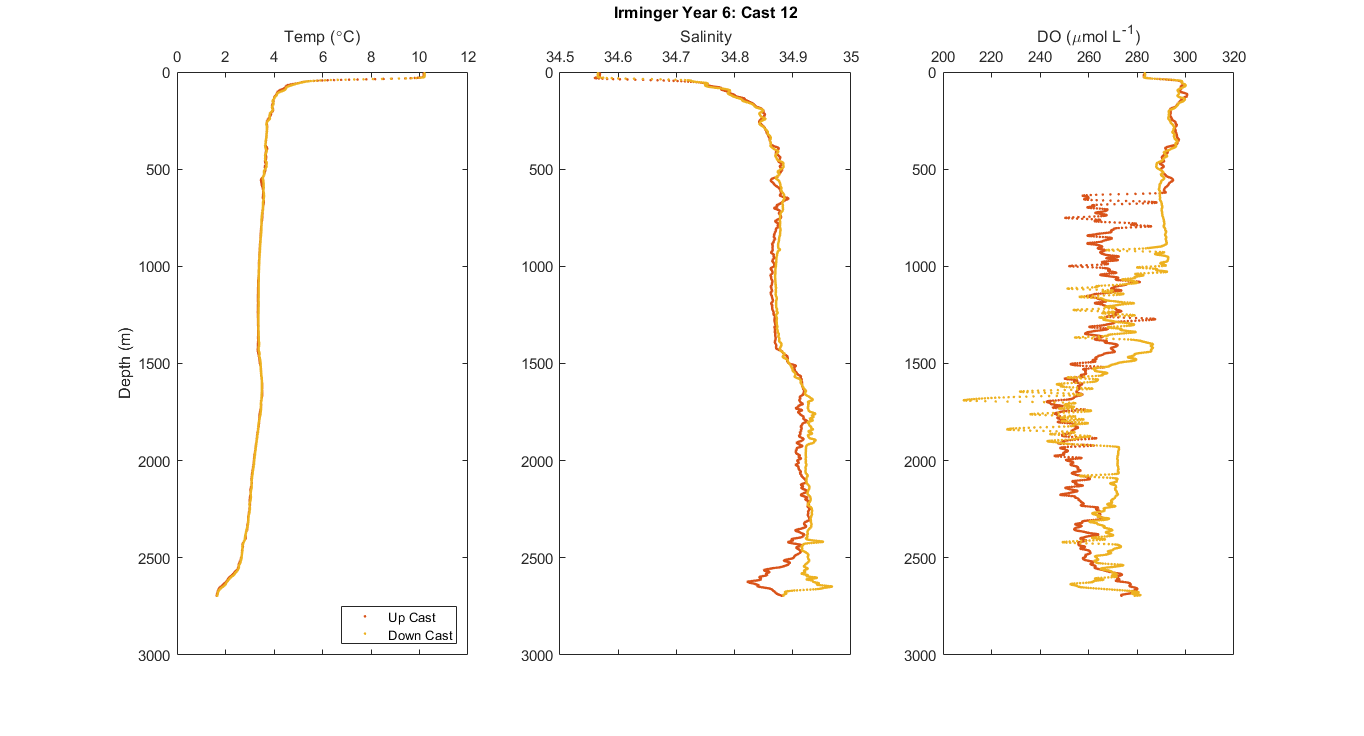


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505012up.t090C,ar3505012up.depSM,'.','Color',red);
hold on
plot(ar3505012down.t090C,ar3505012down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505012up.sal00,ar3505012up.depSM,'.','Color',red);
hold on
plot(ar3505012down.sal00,ar3505012down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 12')

s3 = subplot(1,3,3);
plot(ar3505012up.sbeox0MLL*44.661,ar3505012up.depSM,'.','Color',red);
hold on
plot(ar3505012down.sbeox0MLL*44.661,ar3505012down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

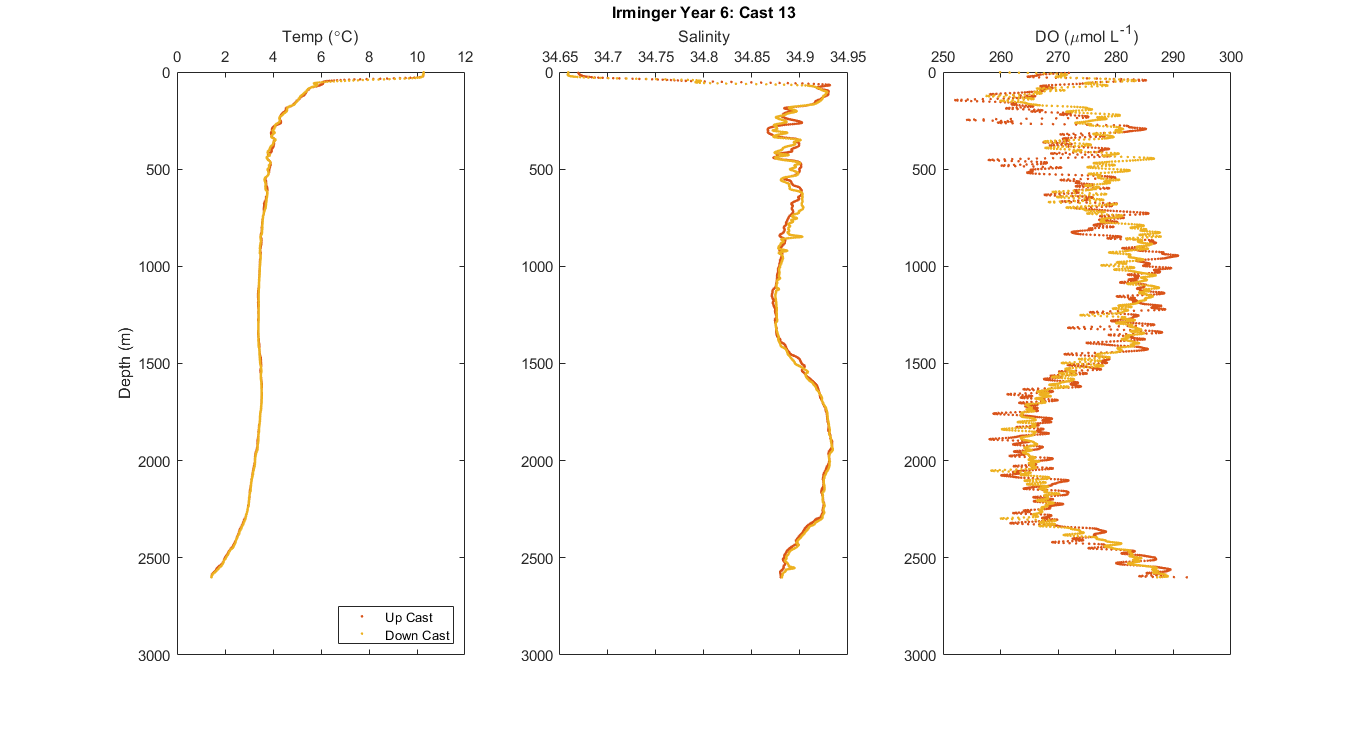


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3505013up.t090C,ar3505013up.depSM,'.','Color',red);
hold on
plot(ar3505013down.t090C,ar3505013down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3505013up.sal00,ar3505013up.depSM,'.','Color',red);
hold on
plot(ar3505013down.sal00,ar3505013down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 6: Cast 13')

s3 = subplot(1,3,3);
plot(ar3505013up.sbeox0MLL*44.661,ar3505013up.depSM,'.','Color',red);
hold on
plot(ar3505013down.sbeox0MLL*44.661,ar3505013down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')